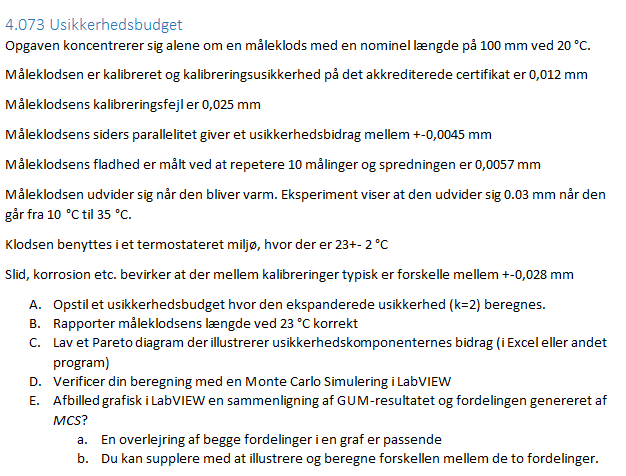

clc; clear;
u = symunit;
format long

kategorier = ["Måleudstyr/reference","Klodsen/dutten","Parallelitet", "" + ...
    "Måleudstyr/fladhed","Målemiljø","Udvidelse"];
typer = ["B","A","A","B","B","A"];
sider = [1,1,2,1,2,1];
fordeling = ["Normal","Normal","Firkant","Trekant/normal","Firkant","Firkant"];
eq_factor = ["2","2","2*sqrt(3)","2*sqrt(6)","2*sqrt(3)","sqrt(3)"];



% Værdier
Lnom = 100*u.mm; % ved 20C
temp = 20 * u.K;

% Usikkerheder
kal_usikkerhed = 0.012*u.mm; % Normal
klods_kal_fejl = 0.025*u.mm; % Normal
klods_side_fejl = 0.0045*u.mm; % Firkant

sigma_flad = 0.0057*u.mm; % N = 10, Trekant

temp_fejl = 2*u.K; % Firkant

udvidelse = 0.03*u.mm;

k = 2;

% Usikkerheder
fejls = [kal_usikkerhed, klods_kal_fejl, klods_side_fejl, sigma_flad, temp_fejl, udvidelse];

% Standardusikkerheder
u_kal_usikkerhed = fejls(1)/sqrt(3)*2;
u_klods_kal_fejl = fejls(2)/2;
u_klods_side_fejl = fejls(3)/(sqrt(3)*2);
u_sigma_flad = fejls(4)/(sqrt(6)*2);
u_temp_fejl = fejls(5)*0.03/25*u.mm/u.K/(sqrt(12));

u_udvidelse = fejls(6)/(sqrt(6));

% Liste over kalibrerede fejl
fejl_list = [u_kal_usikkerhed,u_klods_kal_fejl,u_klods_side_fejl,u_sigma_flad,u_temp_fejl,u_udvidelse];

% Frihedsgrader
dfs = [inf,inf,inf,inf,10,inf]';

sens = [1,1,1,1,0.03/25*u.mm/u.K,1]';

fejl_tot = vpa(sum(fejl_list),3)

$$fejl\_tot = 0.0418\,\mathrm{mm}$$

weight = vpa(fejl_list./fejl_tot * 100',3);


% Antal effektive frihedsgrader (noget højt)
Veff = WelchSatterthwaite(fejl_tot, fejl_list, dfs')

$$Veff = 118787187.09443865947634086581567$$

fejl_tot = fejl_tot

$$fejl\_tot = 0.0418\,\mathrm{mm}$$


t_95 = tinv(0.95,Veff);

% Ekspanderet usikkerhed

U_eks = vpa(fejl_tot * t_95,3)

$$U\_eks = 0.0687\,\mathrm{mm}$$

## Usikkerhedsbudget og paretediagram

varnames = ["Kategorier","Typer","Sider","Fordeling","Ækvi-faktor", "Usikkerhed","Følsomhed","Standard usikkerhed","Frihedsgrader","Vægt"];
disp(table(kategorier', typer', sider', fordeling', eq_factor', vpa(fejls',3), vpa(sens,3) ,vpa(fejl_list',3), dfs, vpa(weight', 2),'VariableNames',varnames))

          Kategorier          Typer    Sider       Fordeling        Ækvi-faktor    Usikkerhed         Følsomhed        Standard usikkerhed    Frihedsgrader    Vægt
    ______________________    _____    _____    ________________    ___________    ___________    _________________    ___________________    _____________    ____
    "Måleudstyr/reference"     "B"       1      "Normal"            "2"            0.012*[mm]     1.0                     0.0139*[mm]              Inf         33.0
    "Klodsen/dutten"           "A"       1      "Normal"            "2"            0.025*[mm]     1.0                     0.0125*[mm]              Inf         30.0
    

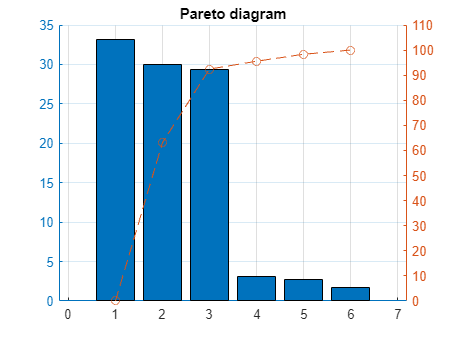



hold on
yyaxis left
w = sort(weight,'descend');

bar(double(w)), title("Pareto diagram"), grid("on")




yyaxis right

for i = 2:length(w)
    ws(i) = sum(w(1, 1:i));
end

plot(ws, '--o')
hold off
ylim([0,110])